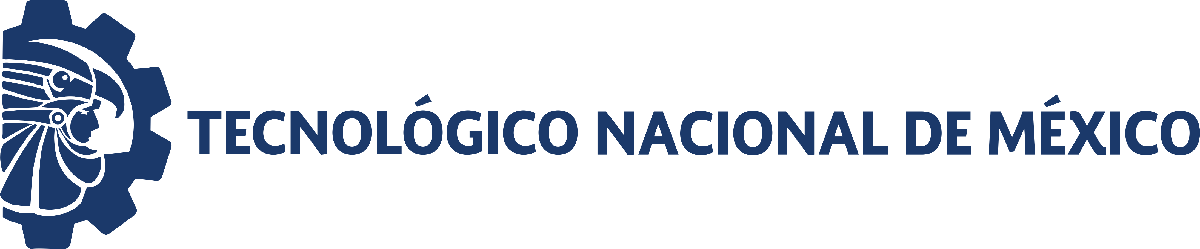                                 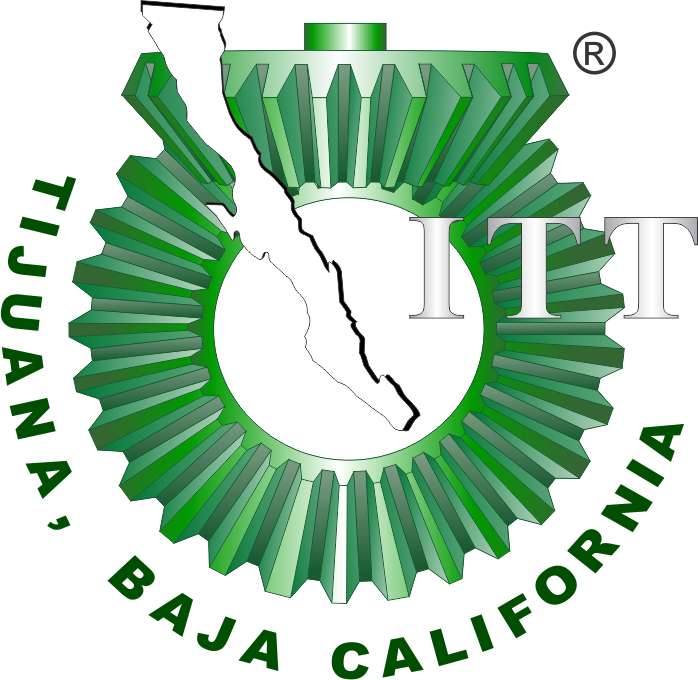

# Práctica cinco: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

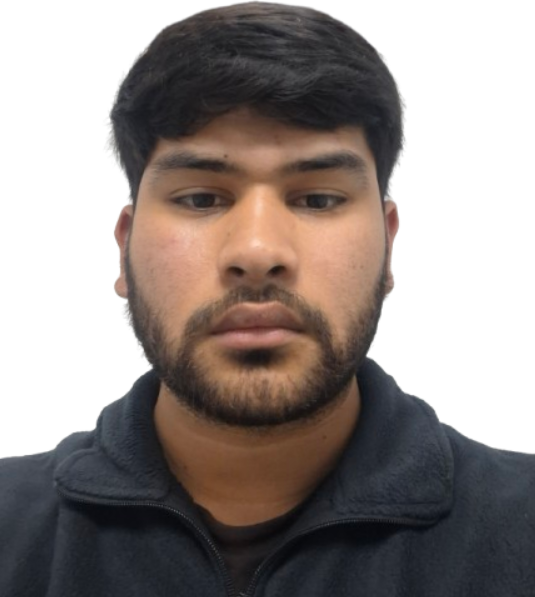

Nombre del alumno: Tapia Garcia Jahzeel Abisai

Número de control: 22210798

Correo institucional: l22210798**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx **

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '15';
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Rendimiento del controlador

kP=Rr/Re

kl= 1/ReCr

kD=RrCe

Setting Time = 0.0891 s

Overshoot = 0.0813%

Peak = 1

## **Respuesta Lazo Abierto**

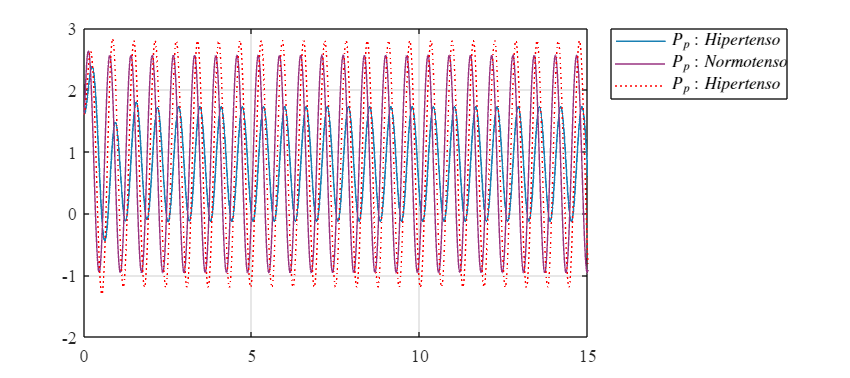

file = 'LazoAbiertoP5';
open_system(file);
x = sim(file,parameters);
opt = 1;
plotsignals(x.t, x.Ppx, x.Ppy, x.Ppz, opt);

## Respuesta Lazo Cerrado (Hipotenso)

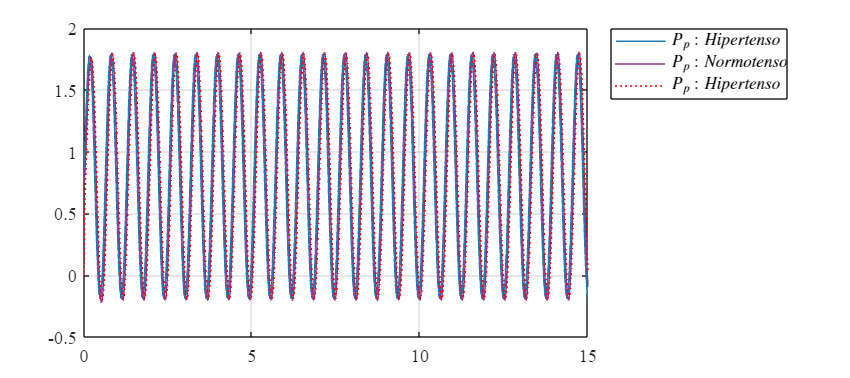

file = 'LazoCerradoHipotenso';
open_system(file);
x = sim(file, parameters);
opt = 2;
plotsignals(x.t, x.Ppx, x.Ppy, x.Ppz, opt);

## Respuesta Lazo Cerrado (Hipertenso)

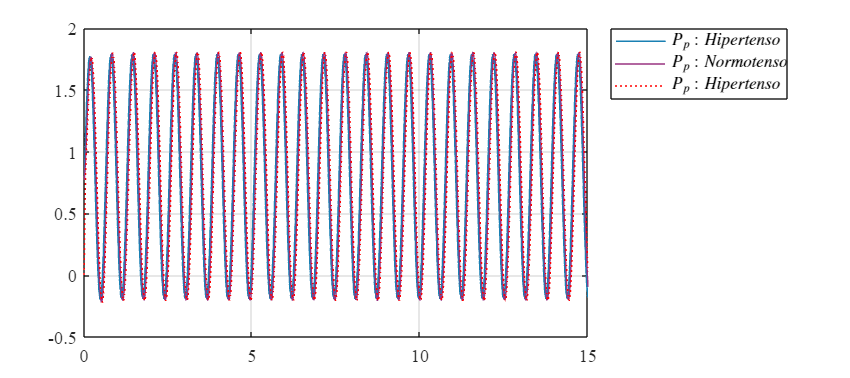

file = 'LazoCerradoHipertenso';
open_system(file);
x = sim(file, parameters);
opt = 3;
plotsignals(x.t, x.Ppx, x.Ppy, x.Ppz, opt);

## Función: Respuesta del sistema con y sin tratamiento

function plotsignals(t, Ppx, Ppy, Ppz, opt)
    set(figure(), 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 18, 8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    
    rojo=[1,0,0];
    morado=[.6,.2,.5];
    azul=[.1,.5,.7];
    
    hold on; grid on; box on;
    
    plot(t, Ppx, 'LineWidth', 1, 'Color', azul);      % Hipetenso
    plot(t, Ppy, 'LineWidth', .5, 'Color', morado);    % Normotenso
    plot(t, Ppz, ':', 'LineWidth', .5, 'Color', rojo); % Tratamiento
    
    
    L = legend('$P_{p}:Hipertenso$', ...
               '$P_{p}:Normotenso$', ...
               '$P_{p}:Hipertenso$');
    set(L, 'Interpreter','Latex','Location','northeastoutside','Box','on');
end
